# Fourier Analysis of the fracture aperture distribution

The objective of this exercise is to implement an idea discussed with Nicola on Friday Feb 25th regarding analyzing fracture specific stiffness. Fracture specific stiffness is defined as "the average applied stressd divided by the average displacement across the fracture interface in excess of the displacement that would occur if the fracture were not present." (Hopkins et al. 1987).

The first thing to do is learn more about Fast-Fourier Transforms (FFT). I will be referring to (Cerna and Harvey, 2000) for guidance in understanding how to use FFT in analysing my data. I want to note that generally speaking, FFT is applied to time-series data i.e. data that change over time. For analysing fractures, we are interested in spacially variable data not time variant, so that will be a distict difference in using FFT.

clearvars; home;

## Example in Matlab documentation (modified for clarity).

The [fft](matlab:doc('fft')) documentation page has the example shown below. Here, the example has been edited for clarity. To access the original example run the following click [here](matlab:openExample('matlab/FFTOfNoisySignalExample')). 

### Define the domain of the calculation

% the sampling frequency must be suffecient to sample the highest
% oscilation frequency. In this case, the max oscilation frequency is
% 12Hz, so sampling frequency of 1000 samples per seconds is sufficient.
samplingFreq        = 1000;                     % Sampling frequency    [samples/sec]             
samplingInterval    = 1/samplingFreq;           % Sampling period       [sec/samples]
tf  = 0.5;                                      % t final               [sec]

% the following produces an even number of samples. This only matters when
% using fft(input) not fft(input,2^nextpow2(length(input))
t   = 0:samplingInterval:tf-samplingInterval;   % Time vector           [sec] 
% the following produced an odd number of samples
% t   = 0:samplingInterval:tf;   % Time vector           [sec]
nSamples = length(t);                           % Length of signal      [samples]

Form a signal containing a 50 Hz sinusoid of amplitude 0.7, a 120 Hz sinusoid of amplitude 1, and a DC shift (0 frequency amplitude) of 0.25;

S = 0.25 + 0.7 * sin(2*pi*50*t) + 1 * sin(2*pi*120*t);

ِCorrupt the signal with zero-mean white noise with a variance of 4.

X = S + 2 * randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal `X(t)`.

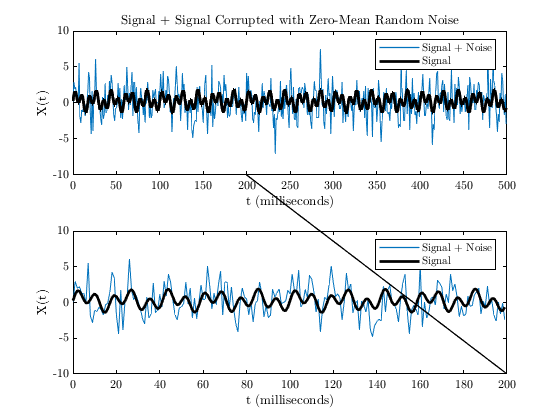

figure
subplot(2,1,1); 
plot(1000*t,X,'DisplayName','Signal + Noise'); hold on;
plot(1000*t,S,'k','DisplayName','Signal','LineWidth',2);
title('Signal + Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend
ax1 = gca;
nsamples = 200;
ax1.XTick = sort(unique([ax1.XTick,nsamples]));

subplot(2,1,2);
plot(1000*t(1:nsamples),X(1:nsamples),'DisplayName','Signal + Noise'); hold on;
plot(1000*t(1:nsamples),S(1:nsamples),'k','DisplayName','Signal','LineWidth',2);
%title('Signal + Signal Corrupted with Zero-Mean Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
legend
ax2 = gca; 
ax2.YLim = ax1.YLim;
% annotations
fig = gcf;

% plot a line between the subplots to relate them to one another
annotation(fig,'line',[ax1.Position(1)+ax1.Position(3)*(nsamples/length(t)) (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);

### Compute the Fourier transform of the signal. 

Y = fft(X);
phi = angle(Y);
% in the following line, nSamples gets overwritten
% % nSamples = 2^nextpow2(length(X)); Y = fft(X,nSamples);

Compute the two-sided spectrum `P2`. Then compute the single-sided spectrum `P1` based on `P2` and the even-valued signal length `L`. 

P2 = abs(Y/length(X));       % we have to normalize by the signal length
P2(2:end) = 2*P2(2:end);    % we have to multiple all frequency amplitudes by 2 except for the zero frequency amplitude
% extract the single-sided spectrum from P2 before shift the 0 frequency to
% the middle
P1 = P2(1:floor(nSamples/2)+1);

Define the frequency domain `f` and plot the single-sided amplitude spectrum `P1, and the double-sided amplitude spectrum P2.` The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.

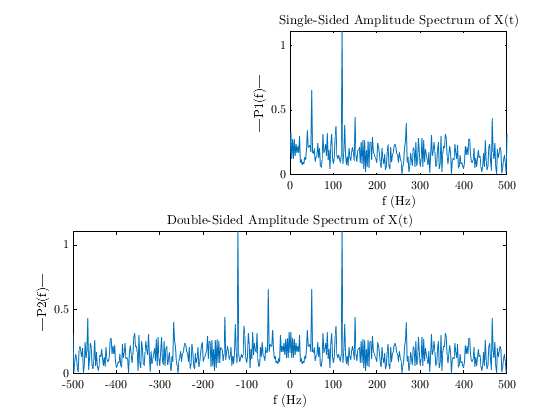

f = (0:(nSamples/2)) * (samplingFreq/nSamples);
fshift  = fftshift(f2fromf1(f,nSamples));
P2shift = fftshift(P2);

figure
subplot(2,2,2);
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');
xlim([0 500]);
ax1 = gca; 

subplot(2,2,3:4);
plot(fshift,P2shift) 
title('Double-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P2(f)|')
ax2 = gca;
ax1.Position([1 3]) = [ax2.Position(1)+ax2.Position(3)/2, ax2.Position(3)/2];  

Now, zoom in to inspect the 0 frequency element in both plots. I'm doing this to make sure that the determination of the edges of `P1` and `P2` is correct.

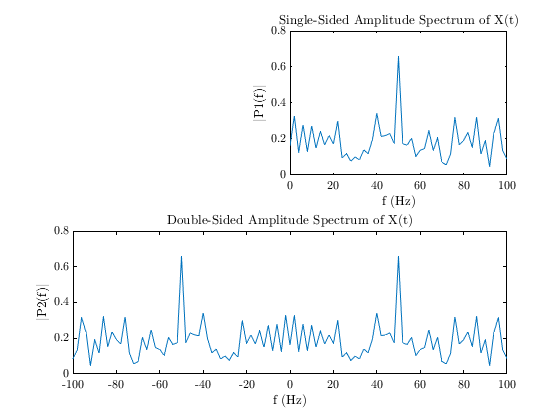

horizontalLim = 100;

figure
subplot(2,2,2);
plot(f,P1);
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('$|$P1(f)$|$');
xlim([0 horizontalLim]);
ax1 = gca; 

subplot(2,2,3:4);
plot(fshift,P2shift) ;
title('Double-Sided Amplitude Spectrum of X(t)');
xlabel('f (Hz)');
ylabel('$|$P2(f)$|$');
xlim([-horizontalLim horizontalLim]);
ax2 = gca;
ax1.Position([1 3]) = [ax2.Position(1)+ax2.Position(3)/2, ax2.Position(3)/2];  

*Copyright 2012 The MathWorks, Inc.*

## Testing helper functions

This is placed here because it used variabels from the section above

### Reconstructing `P2` from `P1`

p1 = P1;
p2 = p2fromp1(p1,nSamples);
P2 - p2 % this should result in an array of 0s

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


trying with freq

f2shift = fftshift(f2fromf1(f,nSamples))

f2shift =   -500  -498  -496  -494  -492  -490  -488  -486  -484  -482  -480  -478  -476  -474  -472  -470  -468  -466  -464  -462  -460  -458  -456  -454  -452  -450  -448  -446  -444  -442  -440  -438  -436  -434  -432  -430  -428  -426  -424  -422  -420  -418  -416  -414  -412  -410  -408  -406  -404  -402


Comparing Y and `yfromp1`

y = yfromp1(p1, phi, nSamples);
zz = [y; Y]

zz = 	1.0e+02 *

   0.8166 + 0.0000i   0.7721 - 0.2795i   0.3128 - 0.0376i  -0.2309 + 0.6576i  -0.3180 + 0.0732i   0.4520 + 0.5078i  -0.0881 - 0.3619i  -0.4788 + 0.3689i   0.0822 + 0.4111i   0.5485 + 0.0292i  -0.0217 - 0.4286i  -0.7417 - 0.1021i   0.1443 - 0.1854i  -0.1658 + 0.2493i   0.1827 - 0.0578i   0.1784 + 0.1763i   0.2069 - 0.0368i  -0.0591 - 0.3444i  -0.0533 - 0.2913i  -0.4228 + 0.2541i   0.8139 + 0.2637i   0.2826 - 0.4540i  -0.2893 + 0.4655i   0.4942 - 0.2941i   0.4092 - 0.1562i   0.4938 - 1.5659i   0.3138 + 0.3002i   0.4131 - 0.0254i  -0.3710 + 0.3545i  -0.2372 + 0.1000i   0.2122 - 0.2716i  -0.3678 + 0.0061i   0.6166 - 0.0487i  -0.1793 + 0.2883i   0.3370 + 0.3909i   0.1758 + 0.0076i  -0.1400 + 0.0152i   0.1587 + 0.2455i   0.2697 - 0.7518i  -0.4126 + 0.0683i  -0.3648 - 0.3152i  -0.5800 + 0.1062i   0.0113 - 0.3821i  -0.7300 - 0.3344i  -0.2344 - 0.1695i  -0.4436 + 0.1877i   0.0515 - 0.1037i  -0.3198 + 0.4931i  -0.7615 + 0.2089i  -0.2670 - 0.2073i
   0.8166 + 0.0000i   0.7721 - 0

## Desconstructing the Matlab example for better understanding

The following [link](https://medium.com/analytics-vidhya/breaking-down-confusions-over-fast-fourier-transform-fft-1561a029b1ab) is useful in guiding through applyig `fft` 

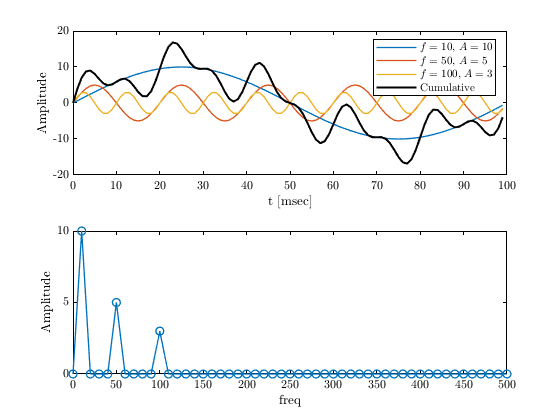

% consider a time series signal that is purely sinosoidal
freq = [10, 50, 100];
amp  = [10, 5, 3];
samplingFreq = 10*max(freq);         % sampling frequencye [sample/time]
samplingInterval = 1/samplingFreq;
tf = 0.1; 
t = 0:samplingInterval:tf-samplingInterval;

y = @(t,f,A) A*sin(2*pi*f*t);

dc = 0; 
x = zeros(size(t));
for i = 1:length(freq)
    x = x + y(t,freq(i),amp(i));
end
% 0 freq (dc) shift
x = x + dc; 

figure
subplot(2,1,1);

for i = 1:length(freq)
    plot(1000*t,y(t,freq(i),amp(i)),'DisplayName',['$f =\ $',num2str(freq(i)), ', $A =\ $',num2str(amp(i))]); hold on;
end

plot(1000*t,x,'-k','DisplayName','Cumulative','LineWidth',1.5); hold on
xlabel('t [msec]');
ylabel('Amplitude');
legend('Location','best');

Y = fft(x);
nSamples = length(t);

% in the following, normalizing by the number of samples is simply part of
% the algorith. I did not look much further into it, and I don't think it
% matters too much
P2 = abs(Y/nSamples);

% computing the signle side band, or singles-sided spectrum, we take the
% first half of P2. Note that P2(1) is the DC or zero-frequencye componenet
P1 = P2(1:floor(nSamples/2)+1);

% since the first element of the P1 is the DC element, we multiple the rest
% by 2 which is equivalent to applying the Hilbert transform (based on the
% link above!)
P1(2:end) = 2*P1(2:end);
 
% to find the x-axis, we need to do the following. I need to study this
% further to better understand it.
freqFFT = (0:1:fix(nSamples/2))*(samplingFreq/nSamples);

subplot(2,1,2);
plot(freqFFT,P1,'-o')
%xlim([freqFFT(1) freqFFT(end)]);
ylabel('Amplitude');
xlabel('freq');

## Performing the same analysis as the section above using helper functions

% consider a time series signal that is purely sinosoidal
freq = [10, 50, 100];
amp  = [10, 5, 3];
samplingFreq = 10*max(freq);         % sampling frequencye [sample/time]
samplingInterval = 1/samplingFreq;
tf = 0.1; 
t = 0:samplingInterval:tf-samplingInterval;

y = @(t,f,A) A*sin(2*pi*f*t);

dc = 0; 
x = zeros(size(t));
for i = 1:length(freq)
    x = x + y(t,freq(i),amp(i));
end
% 0 freq (dc) shift
x = x + dc; 

figure
subplot(2,1,1);

for i = 1:length(freq)
    plot(1000*t,y(t,freq(i),amp(i)),'DisplayName',['$f =\ $',num2str(freq(i)), ', $A =\ $',num2str(amp(i))]); hold on;
end

plot(1000*t,x,'-k','DisplayName','Cumulative','LineWidth',1.5); hold on
xlabel('t [msec]');
ylabel('Amplitude');
legend('Location','best');

result = myfft(x, samplingFreq);

subplot(2,1,2);
plot(result.f1, result.p1,'-o')
%xlim([freqFFT(1) freqFFT(end)]);
ylabel('Amplitude');
xlabel('freq');

# 2D FFT

Here we try to generate a 2D fft and see how it looks. Starting by defining an image resolution of `33.3 um, this resolution defines the sampling frequency in our image first then apply the analysis. `

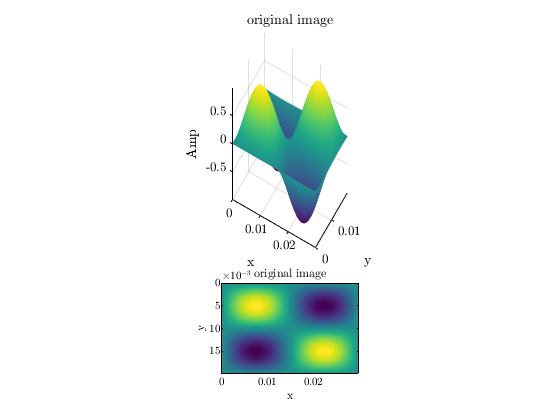

umpermm = 1e3;                  % [micrometer / milimeter]
crackDx = 33.3 *1e-6;                % [m]
samplingFreqX = 1/crackDx;           % [sample/m]
dy = crackDx;                        % [m]
samplingFreqY = 1/dy;           % [sample/m]
xmax = 30 * 1e-3;               % [m]
ymax = 20 * 1e-3;               % [m]

% define the span of the image
X = 0:crackDx:xmax-crackDx;
nSampleX = length(X);

Y = 0:dy:ymax-dy;
nSampleY = length(Y);

[x,y] = meshgrid(X,Y);

% define the rotation of the waves with respect to the z-axis (deg is the
% degree of rotation using the right-hand-rule where the thumb is aligned
% with the z-axis)
deg = 0;

[x, y] = getRotated2DCoordinates(x,y,deg); 

% defining the spatial frequencies of the image sinosoids
nCyclesX = 1;
lambdaX = xmax / (nCyclesX);            % [m] the wavelength in the x-direction
freqX = 1/lambdaX;

nCyclesY = 1;
lambdaY = ymax / (nCyclesY);
freqY = 1/lambdaY;

% defining the amplitude and the zero-frequency shift
A = 1;
A0 = 0; 

% generating the image
z = A0 + A .* sin(2*pi*x*freqX) .* sin(2*pi*y*freqY); 

% plotting the image
figure
subplot(3,2,1:4);
surf(X,Y,z);
shading interp
axis image
view([30 89.00]);
xlabel('x');
ylabel('y');
zlabel('Amp');
title('original image');
subplot(3,2,[5,6])
imagesc(X,Y,z);
%shading interp
axis image
%view([0.60 90.00]);
xlabel('x');
ylabel('y');
zlabel('Amp');
title('original image');

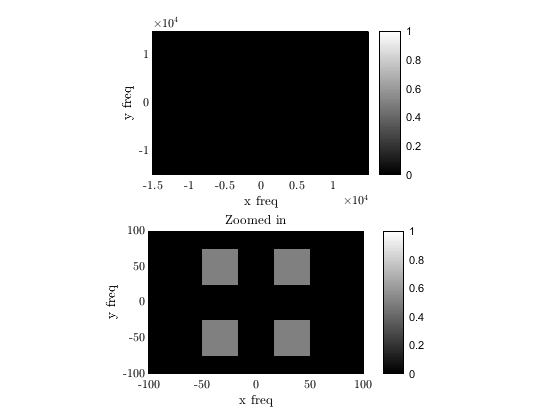


% calculating the fft
% zfft = fft2(z,2^nextpow2(length(Y)),2^nextpow2(length(X)));
zfft = fft2(z);
clear P2
P2 = abs(zfft*(1/nSampleX)*(1/nSampleY));

% extract the DC componenet (0-freq amplitude)
dc = P2(1,1);

% multiply everything by 2. Maybe this needs to be multiplied by 2^2 since
% it is a 2d image??
P2 = 2 * P2;

% reassign the DC componenet
P2(1,1) = dc;

% shift the DC component to the center of the image
P2centered = fftshift(P2); 

% determing the x and y axis in the frequency domain
fshiftX = (-nSampleX/2:nSampleX/2-1)*(samplingFreqX/nSampleX);
fshiftY = (-nSampleY/2:nSampleY/2-1)*(samplingFreqY/nSampleY);

% plotting the amplitudes in the frequency domain
figure
subplot(2,1,1)
imagesc(fshiftX,fshiftY,P2centered);
shading flat;
ax1 = gca;
ax1.CLim = [0 A]; colorbar
ax1.YDir = 'normal';
%axis equal
colormap gray;
xlabel('x freq');
ylabel('y freq');
%xlim([-2 2]);
%xlim(freqX*[-2 2]);
%ylim(0.1*[-1 1]);
ax1.DataAspectRatio = [1 nSampleX/nSampleY 1]; % this works only with the current configuration

% zoomed in version
subplot(2,1,2)
imagesc(fshiftX,fshiftY,P2centered);
shading flat;
ax2 = gca;
ax2.CLim = [0 A]; colorbar
ax2.YDir = 'normal';
%axis equal
colormap gray;
xlabel('x freq');
ylabel('y freq');
title('Zoomed in');
xlim(max([freqX freqY])*[-2 2]);
ylim(max([freqX freqY])*[-2 2]);
ax2.DataAspectRatio = [1 nSampleX/nSampleY 1]; % this works only with the current configuration

# Applying FFT on a synthetic crack image

Considering the model of a tappered crack as shown in *Mavko and Nur (1978).*

### *Generating a synthetic image with a single fracture*

#### *Starting with the 1D profiles plotted twice, once with a positive sign, and once with a negative sign*

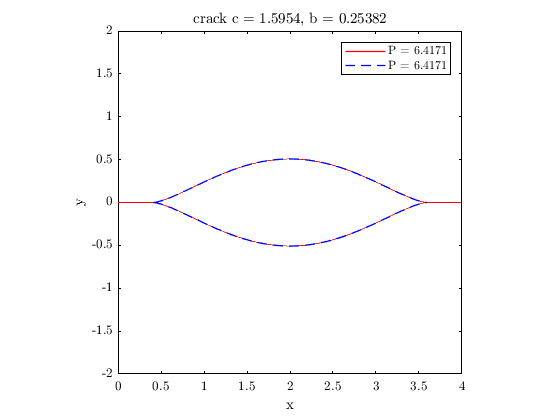

clear dx dy X Y x y crack;

% crack original properties
original.c = 2;      % half crack width
original.b = .5;      % half crack aperture (not really, it seems like it cracks aperture/4)
original.x0 = original.c;

% matrix material properties. Considering Calcite properteis (The Rock Physics
% Handbook table A.4.1 in the appendix)
material.K = 76.8;
material.mu = 32.0;
material.nu = 0.32;
material.E = 2*material.mu*(1+material.nu);     % see table 2.2.1 page 23 on The Rock Physics Handbook

% looking at a 1D profile
dx = 1e-2;  % defining a fixed resolution

pClosing = 3/(4*(1-material.nu.^2))*((original.b/original.c)*material.E)-eps*1e1; % subtracted a small amout to avoid nans
p  = linspace(0,pClosing,12);
deg = 0; % deg ~= 0, not implemented yet
for i = length(p):-1:1  % this so I can pre-allocate the size of crack struct correctly
    crack(i) = getCrack(material, original, dx, deg, p(i));
end


% plotting
j = 5;
figure
l(1) = plot(real(crack(j).x), real(crack(j).yplus),'r','DisplayName',['P = ',num2str(crack(j).P)]); hold on;
l(2) = plot(real(crack(j).x), real(crack(j).yminus),'r','DisplayName',['P = ',num2str(crack(j).P)]);

l(3) = plot(real(crack(j).x2), real(crack(j).yplus2),'--b','DisplayName',['P = ',num2str(crack(j).P)]);
l(4) = plot(real(crack(j).x2), real(crack(j).yminus2),'--b','DisplayName',['P = ',num2str(crack(j).P)]);

legend([l(1),l(3)]);
xlabel('x');
ylabel('y');
title(['crack c = ',num2str(crack(j).c),', b = ',num2str(crack(j).b)]);
axis equal
xlim([-crack(j).c0+crack(j).x0 crack(j).c0+crack(j).x0]);
ylim([-crack(j).c0 crack(j).c0]);

#### Plot repeaeated idealized fracture

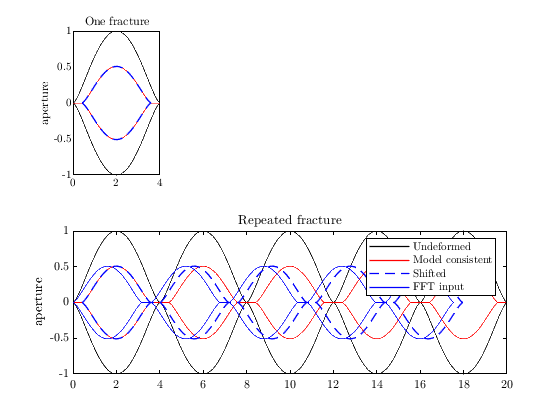

nreplicates = 5;

figure;
subplot(2,nreplicates,1);
l2(1) = plot(crack(1).x, real(crack(1).yplus),'k'); hold on;
l2(2) = plot(crack(1).x, real(crack(1).yminus),'k');
l2(3) = plot(crack(j).x, real(crack(j).yplus),'r');
l2(3) = plot(crack(j).x, real(crack(j).yminus),'r');
l2(5) = plot(crack(j).x2, real(crack(j).yplus2),'--b');
l2(6) = plot(crack(j).x2, real(crack(j).yminus2),'--b');
title('One fracture');
ylabel('aperture');
ax1 = gca;

[repeatedx, repeatedCrackYPlus]          = getReplicatesAlongX(crack(1).x, real(crack(1).yplus), nreplicates);
[~,         repeatedCrackYMinus]         = getReplicatesAlongX(crack(1).x, real(crack(1).yminus), nreplicates);
[~,         repeatedCrackYPlusDef]       = getReplicatesAlongX(crack(j).x, real(crack(j).yplus), nreplicates);
[~,         repeatedCrackYMinusDef]      = getReplicatesAlongX(crack(j).x, real(crack(j).yminus), nreplicates);
[repatedx2, repeatedCrackYPlusDef2]      = getReplicatesAlongX(crack(j).x2, real(crack(j).yplus2), nreplicates);
[~,         repeatedCrackYMinusDef2]     = getReplicatesAlongX(crack(j).x2, real(crack(j).yminus2), nreplicates);

subplot(2,nreplicates,nreplicates+1:2*nreplicates);
l3(1) = plot(repeatedx,repeatedCrackYPlus,'k','DisplayName','Undeformed'); hold on;
l3(2) = plot(repeatedx,repeatedCrackYMinus,'k');
l3(3) = plot(repeatedx,repeatedCrackYPlusDef,'r','DisplayName','Model consistent');
l3(4) = plot(repeatedx,repeatedCrackYMinusDef,'r');
l3(5) = plot(repatedx2,repeatedCrackYPlusDef2,'--b','DisplayName','Shifted');
l3(6) = plot(repatedx2,repeatedCrackYMinusDef2,'--b');
l3(7) = plot(repatedx2-repatedx2(1),repeatedCrackYPlusDef2,'b','DisplayName','FFT input');
l3(8) = plot(repatedx2-repatedx2(1),repeatedCrackYMinusDef2,'b');
legend([l3(1) l3(3) l3(5) l3(7)]);
title('Repeated fracture');
ylabel('aperture');
ax2 = gca;
ax2.XLim = [min([repeatedx(:); repatedx2(:)]) max([repeatedx(:); repatedx2(:)])];
ax1.Position(3) = ax2.Position(3)/nreplicates;

#### Generating a 2D binary image of the fracture

Original crack

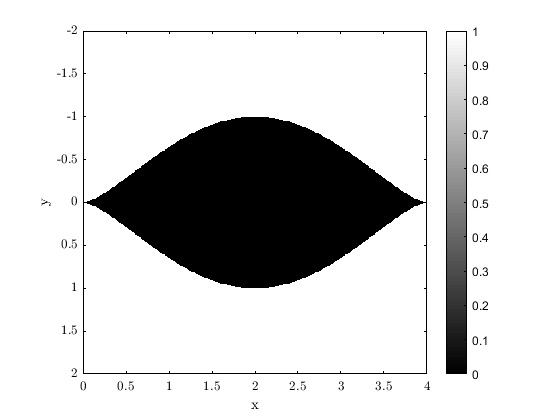

crackBinary = getCrackBinary(crack(1));

figure
imagesc(crackBinary.x,crackBinary.y,crackBinary.image);
xlabel('x');
ylabel('y');
colorbar
colormap gray
axis image
xlim([-original.c+original.x0 original.c+original.x0]);
ylim([-original.c original.c]);

Deformed crack

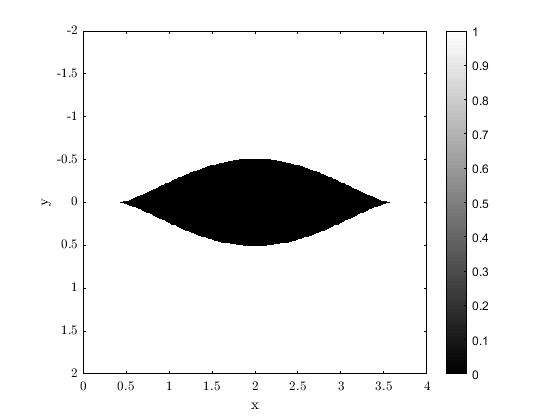

crackBinary = getCrackBinary(crack(j));

figure
imagesc(crackBinary.x,crackBinary.y,crackBinary.image);
xlabel('x');
ylabel('y');
colorbar
colormap gray
axis image
xlim([-original.c+original.x0 original.c+original.x0]);
ylim([-original.c original.c]);

### Looking at the variation in permeability with Pressure

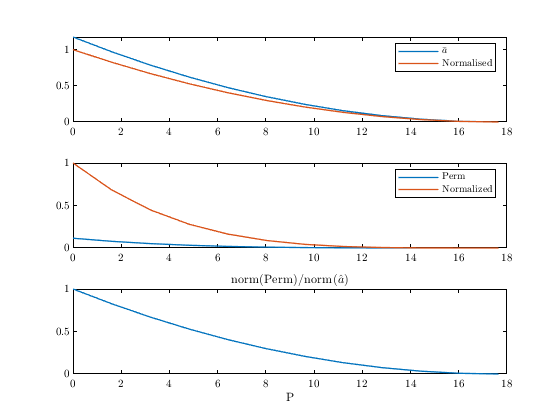

m = 1;
tmp = [crack(:).apertureMean];
tmp2= (1:4:length(crack)*4)+m-1;
apertureMean = tmp(tmp2);
figure
subplot(3,1,1)
plot([crack(:).P],apertureMean,'DisplayName','$\bar{a}$'); hold on;
plot([crack(:).P],apertureMean/max(apertureMean),'DisplayName','Normalised');
legend();
subplot(3,1,2);
plot([crack(:).P],apertureMean.^2/12,'DisplayName','Perm'); hold on;
plot([crack(:).P],(apertureMean.^2/12)./(max(apertureMean.^2/12)),'DisplayName','Normalized');
legend();

subplot(3,1,3); 
plot([crack(:).P],(apertureMean.^2/12)./(max(apertureMean.^2/12))./(apertureMean/max(apertureMean)),'DisplayName','Normalized'); hold on;
title('norm(Perm)/norm($\hat{a}$)')
xlabel('P');

clear tmp tmp2;

### Looking at the variation of fracture aperture with varying pressure

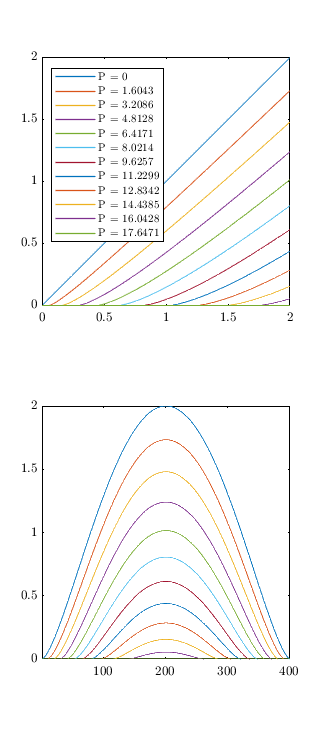

fig = figure('Position',[100 100 320 740]);
m = 1;
subplot(2,1,1);
for n = m:length(crack)
    plot(2*real(crack(m).yplus), 2*real(crack(n).yplus),'DisplayName',['P = ',num2str(crack(n).P)]); hold on;
end
legend('Location','northwest');
axis equal square

subplot(2,1,2); 
for n = m:length(crack)
    plot(2*real(crack(n).yplus),'DisplayName',['P = ',num2str(crack(n).P)]); hold on;
end
axis tight

The first plot shows the reduction of fracture aperture as pressure increases.

The second plot shows what the fracture aperture looks like spati

### 1D FFT on the fracture aperture profile

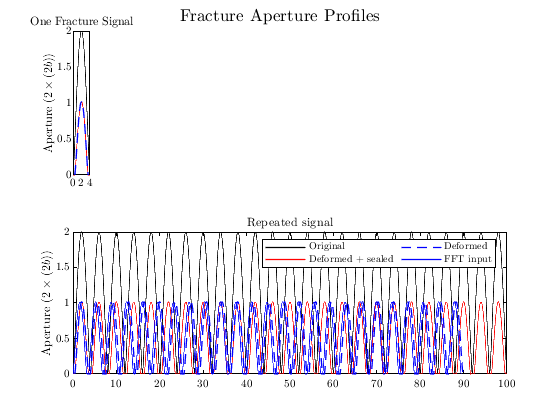

clear x y;

nreplicates = 25;

figure;
subplot(2,nreplicates,1);
plot(crack(1).x, crack(1).aperture,'k'); hold on;
plot(crack(j).x,crack(j).aperture,'r');
plot(crack(j).x2, crack(j).aperture2,'--b');
title('One Fracture Signal');
ylabel('Aperture ($2\times(2b)$)');
ax1 = gca;

[repeatedx, crackRepeatedAperture]          = getReplicatesAlongX(crack(1).x, crack(1).aperture, nreplicates);
[~, crackDeformedRepatedAperture]           = getReplicatesAlongX(crack(j).x, crack(j).aperture, nreplicates);
[repatedx2, crackDeformedRepatedAperture2]  = getReplicatesAlongX(crack(j).x2, crack(j).aperture2, nreplicates);

subplot(2,nreplicates,nreplicates+1:2*nreplicates);
plot(repeatedx,crackRepeatedAperture,'k','DisplayName','Original'); hold on;
plot(repeatedx,crackDeformedRepatedAperture,'r','DisplayName','Deformed + sealed');
plot(repatedx2,crackDeformedRepatedAperture2,'--b','DisplayName','Deformed');
plot(repatedx2-repatedx2(1),crackDeformedRepatedAperture2,'b','DisplayName','FFT input');
title('Repeated signal');
ylabel('Aperture ($2\times(2b)$)');
ax2 = gca;
legend('Location','northeast','NumColumns',2);

sgtitle('Fracture Aperture Profiles');

ax2.XLim = [min([repeatedx(:); repatedx2(:)]) max([repeatedx(:); repatedx2(:)])];
ax1.Position(3) = ax2.Position(3)/nreplicates;

Now we look at the FFT of the aperture deviation from the mean. In regards to the distorted apertures, the ones where the zero aperture interval is removed, my confidance in the plot below isn't great. The reason for that is that I'm plotting only a portion of the frequencies of the original crack as the length of the frequency vector for the distorted crack is smaller.

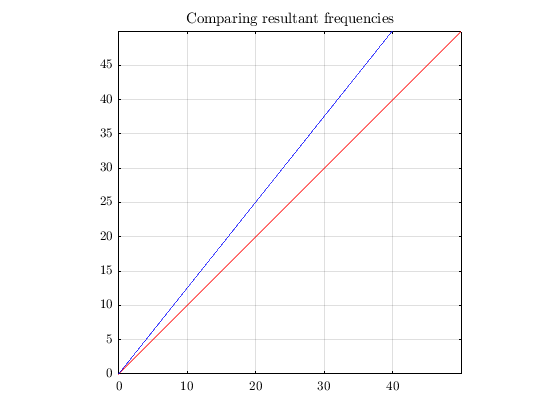

crackFFTResult = myfft(crackRepeatedAperture,1/dx); 
crackDeformedFFTResult  = myfft(crackDeformedRepatedAperture, 1/dx);
crackDeformedFFTResult2 = myfft(crackDeformedRepatedAperture2, 1/dx);
figure
plot(crackFFTResult.f1, crackDeformedFFTResult.f1,'r'); hold on;
plot(crackFFTResult.f1(1:length(crackDeformedFFTResult2.f1)), crackDeformedFFTResult2.f1,'b');
title('Comparing resultant frequencies');   
axis equal; grid on;
xlim([0 max(crackFFTResult.f1)]);
ylim([0 max(crackFFTResult.f1)]);

### Looking at frequency vs amplitude

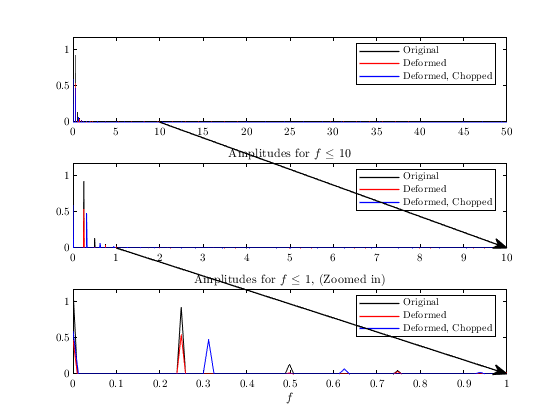

figure
subplot(3,1,1);
plot(crackFFTResult.f1, crackFFTResult.p1,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.f1, crackDeformedFFTResult.p1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.f1, crackDeformedFFTResult2.p1,'b','DisplayName','Deformed, Chopped');
ax1 = gca;
maxShownFreq= ax1.XLim(end);
legend('Location','northeast');

subplot(3,1,2);
plot(crackFFTResult.f1, crackFFTResult.p1,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.f1, crackDeformedFFTResult.p1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.f1, crackDeformedFFTResult2.p1,'b','DisplayName','Deformed, Chopped');

maxShownFreq2 = 10;
title(['Amplitudes for $f \le$ ',num2str(maxShownFreq2)])
ax2 = gca;
ax2.XLim = [0 maxShownFreq2];
legend('Location','northeast');


subplot(3,1,3);
plot(crackFFTResult.f1, crackFFTResult.p1,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.f1, crackDeformedFFTResult.p1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.f1, crackDeformedFFTResult2.p1,'b','DisplayName','Deformed, Chopped');

maxShownFreq3 = 1;
ax3 = gca;
ax3.XLim = [0 maxShownFreq3];
title(['Amplitudes for $f \le$ ',num2str(maxShownFreq3),', (Zoomed in)']); 
legend('Location','northeast');
xlabel('$f$');
fig2 = gcf;

% plot a line between the subplots to relate them to one another
annotation(fig2,'arrow',[ax1.Position(1)+ax1.Position(3)*(maxShownFreq2/maxShownFreq)  (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);
annotation(fig2,'arrow',[ax2.Position(1)+ax2.Position(3)*(maxShownFreq3/maxShownFreq2) (ax3.Position(1)+ax3.Position(3))],[ax2.Position(2) ax3.Position(2)]);

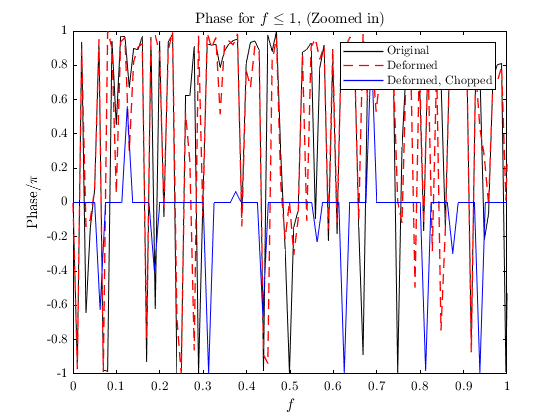


figure
plot(crackFFTResult.f1, crackFFTResult.phi1/pi,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.f1, crackDeformedFFTResult.phi1/pi,'--r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.f1, crackDeformedFFTResult2.phi1/pi,'b','DisplayName','Deformed, Chopped');

title(['Phase for $f \le$ ',num2str(maxShownFreq3),', (Zoomed in)']); 
legend('Location','northeast');
xlabel('$f$');
ylabel('Phase/$\pi$')
ax4 = gca; 
ax4.XLim = [0 maxShownFreq3];

### Looking at the wavelength vs amplitude

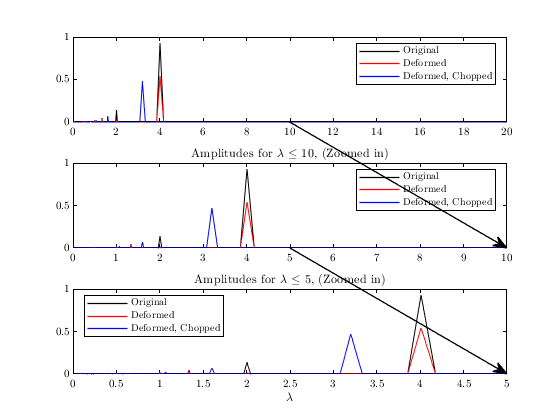

figure
subplot(3,1,1);
plot(crackFFTResult.lambda, crackFFTResult.lambdaP1,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.lambda, crackDeformedFFTResult.lambdaP1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.lambda, crackDeformedFFTResult2.lambdaP1,'b','DisplayName','Deformed, Chopped');
ax1 = gca;
maxShownLambda= 20;
ax1.XLim(2) = maxShownLambda;
legend('Location','northeast');

subplot(3,1,2);
plot(crackFFTResult.lambda, crackFFTResult.lambdaP1,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.lambda, crackDeformedFFTResult.lambdaP1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.lambda, crackDeformedFFTResult2.lambdaP1,'b','DisplayName','Deformed, Chopped');

maxShownLambda2 = 10;
title(['Amplitudes for $\lambda \le$ ',num2str(maxShownLambda2),', (Zoomed in)'])
ax2 = gca;
ax2.XLim = [0 maxShownLambda2];
legend('Location','northeast');


subplot(3,1,3);
plot(crackFFTResult.lambda, crackFFTResult.lambdaP1,'k','DisplayName','Original'); hold on;
plot(crackDeformedFFTResult.lambda, crackDeformedFFTResult.lambdaP1,'r','DisplayName','Deformed');
plot(crackDeformedFFTResult2.lambda, crackDeformedFFTResult2.lambdaP1,'b','DisplayName','Deformed, Chopped');

maxShownLambda3 = 5;
ax3 = gca;
ax3.XLim = [0 maxShownLambda3];
title(['Amplitudes for $\lambda \le$ ',num2str(maxShownLambda3),', (Zoomed in)']); 
legend('Location','northwest');
xlabel('$\lambda$')

fig2 = gcf;

% plot a line between the subplots to relate them to one another
annotation(fig2,'arrow',[ax1.Position(1)+ax1.Position(3)*(maxShownLambda2/maxShownLambda)  (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);
annotation(fig2,'arrow',[ax2.Position(1)+ax2.Position(3)*(maxShownLambda3/maxShownLambda2) (ax3.Position(1)+ax3.Position(3))],[ax2.Position(2) ax3.Position(2)]);

## Plotting the deviation from the mean

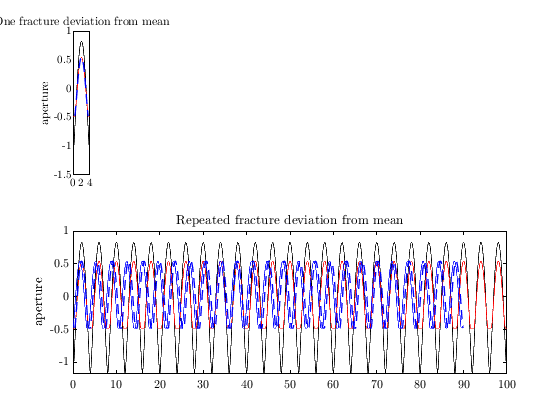

figure;
subplot(2,nreplicates,1);
plot(crack(1).x, crack(1).apertureDeviationFromMean,'k'); hold on;
plot(crack(j).x, crack(j).apertureDeviationFromMean(1,:),'r');
plot(crack(j).x2, crack(j).apertureDeviationFromMean2(1,:),'--b');
title('One fracture deviation from mean');
ylabel('aperture');
ax1 = gca;

[repeatedx, crackRepeatedDeviationFromMean]          = getReplicatesAlongX(crack(1).x, crack(1).apertureDeviationFromMean(1,:), nreplicates);
[~, crackDeformedRepatedDeviationFromMean]           = getReplicatesAlongX(crack(j).x, crack(j).apertureDeviationFromMean(1,:), nreplicates);
[repatedx2, crackDeformedRepatedDeviationFromMean2]  = getReplicatesAlongX(crack(j).x2, crack(j).apertureDeviationFromMean2(1,:), nreplicates);

subplot(2,nreplicates,nreplicates+1:2*nreplicates);
l4(1) = plot(repeatedx,crackRepeatedDeviationFromMean(1,:),'k'); hold on;
l4(2) = plot(repeatedx,crackDeformedRepatedDeviationFromMean(1,:),'r');
l4(3) = plot(repatedx2,crackDeformedRepatedDeviationFromMean2(1,:),'--b');
l4(4) = plot(repatedx2-repatedx2(1),crackDeformedRepatedDeviationFromMean2(1,:),'b');
title('Repeated fracture deviation from mean');
ylabel('aperture');
ax2 = gca;
ax2.XLim = [min([repeatedx(:); repatedx2(:)]) max([repeatedx(:); repatedx2(:)])];
ax1.Position(3) = ax2.Position(3)/nreplicates;

Now we look at the FFT of the aperture deviation from the mean. In regards to the distorted apertures, the ones where the zero aperture interval is removed, my confidance in the plot below isn't great. The reason for that is that I'm plotting only a portion of the frequencies of the original crack as the length of the frequency vector for the distorted crack is smaller.

crackDeviationFromMeanFFTResult = myfft(crackRepeatedDeviationFromMean, 1/dx); 
crackDeviationFromMeanDeformedFFTResult  = myfft(crackDeformedRepatedDeviationFromMean, 1/dx);
crackDeviationFromMeanDeformedFFTResult2 = myfft(crackDeformedRepatedDeviationFromMean2, 1/dx);
figure
plot(crackDeviationFromMeanFFTResult.f1, crackDeviationFromMeanDeformedFFTResult.f1,'r'); hold on;
plot(crackDeviationFromMeanFFTResult.f1(1:length(crackDeviationFromMeanDeformedFFTResult2.f1)), crackDeviationFromMeanDeformedFFTResult2.f1,'b');
title('Comparing resultant frequencies');   
axis equal; grid on;
xlim([0 max(crackDeviationFromMeanFFTResult.f1)]);
ylim([0 max(crackDeviationFromMeanFFTResult.f1)]);

#### Looking at frequency vs amplitude

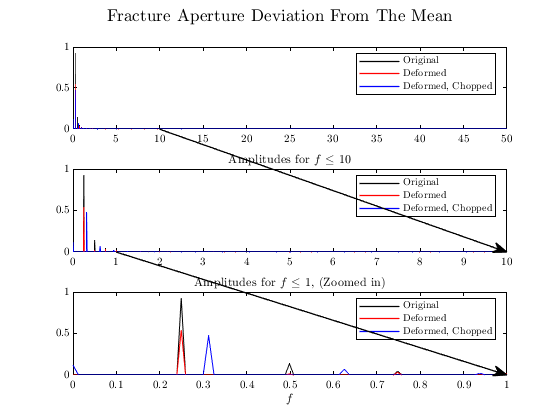

figure
subplot(3,1,1);
plot(crackDeviationFromMeanFFTResult.f1, crackDeviationFromMeanFFTResult.p1,'k','DisplayName','Original'); hold on;
plot(crackDeviationFromMeanDeformedFFTResult.f1, crackDeviationFromMeanDeformedFFTResult.p1,'r','DisplayName','Deformed');
plot(crackDeviationFromMeanDeformedFFTResult2.f1, crackDeviationFromMeanDeformedFFTResult2.p1,'b','DisplayName','Deformed, Chopped');
ax1 = gca;
maxShownFreq= ax1.XLim(end);
legend('Location','northeast');

subplot(3,1,2);
plot(crackDeviationFromMeanFFTResult.f1, crackDeviationFromMeanFFTResult.p1,'k','DisplayName','Original'); hold on;
plot(crackDeviationFromMeanDeformedFFTResult.f1, crackDeviationFromMeanDeformedFFTResult.p1,'r','DisplayName','Deformed');
plot(crackDeviationFromMeanDeformedFFTResult2.f1, crackDeviationFromMeanDeformedFFTResult2.p1,'b','DisplayName','Deformed, Chopped');

maxShownFreq2 = 10;

title(['Amplitudes for $f \le$ ',num2str(maxShownFreq2)])
ax2 = gca;
ax2.XLim = [0 maxShownFreq2];
legend('Location','northeast');


subplot(3,1,3);
plot(crackDeviationFromMeanFFTResult.f1, crackDeviationFromMeanFFTResult.p1,'k','DisplayName','Original'); hold on;
plot(crackDeviationFromMeanDeformedFFTResult.f1, crackDeviationFromMeanDeformedFFTResult.p1,'r','DisplayName','Deformed');
plot(crackDeviationFromMeanDeformedFFTResult2.f1, crackDeviationFromMeanDeformedFFTResult2.p1,'b','DisplayName','Deformed, Chopped');

maxShownFreq3 = 1;
ax3 = gca;
ax3.XLim = [0 maxShownFreq3];
title(['Amplitudes for $f \le$ ',num2str(maxShownFreq3),', (Zoomed in)']); 
legend('Location','northeast');
xlabel('$f$');

fig2 = gcf;

% plot a line between the subplots to relate them to one another
sgtitle('Fracture Aperture Deviation From The Mean'); pause(.02); % the pause is to help the super title to render correctly (shrug)
annotation(fig2,'arrow',[ax1.Position(1)+ax1.Position(3)*(maxShownFreq2/maxShownFreq)  (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);
annotation(fig2,'arrow',[ax2.Position(1)+ax2.Position(3)*(maxShownFreq3/maxShownFreq2) (ax3.Position(1)+ax3.Position(3))],[ax2.Position(2) ax3.Position(2)]);

#### Looking at the wavelength vs amplitude

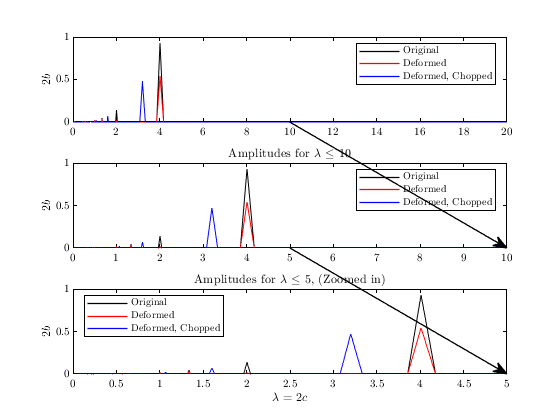

figure
subplot(3,1,1);
plot(crackDeviationFromMeanFFTResult.lambda, crackDeviationFromMeanFFTResult.lambdaP1,'k','DisplayName','Original'); hold on;
plot(crackDeviationFromMeanDeformedFFTResult.lambda, crackDeviationFromMeanDeformedFFTResult.lambdaP1,'r','DisplayName','Deformed');
plot(crackDeviationFromMeanDeformedFFTResult2.lambda, crackDeviationFromMeanDeformedFFTResult2.lambdaP1,'b','DisplayName','Deformed, Chopped');
ylabel('$2b$');
ax1 = gca;
maxShownLambda= 20;
ax1.XLim(2) = maxShownLambda;
legend('Location','northeast');

subplot(3,1,2);
plot(crackDeviationFromMeanFFTResult.lambda, crackDeviationFromMeanFFTResult.lambdaP1,'k','DisplayName','Original'); hold on;
plot(crackDeviationFromMeanDeformedFFTResult.lambda, crackDeviationFromMeanDeformedFFTResult.lambdaP1,'r','DisplayName','Deformed');
plot(crackDeviationFromMeanDeformedFFTResult2.lambda, crackDeviationFromMeanDeformedFFTResult2.lambdaP1,'b','DisplayName','Deformed, Chopped');

maxShownLambda2 = 10;
title(['Amplitudes for $\lambda \le$ ',num2str(maxShownLambda2)])
ylabel('$2b$');
ax2 = gca;
ax2.XLim = [0 maxShownLambda2];
legend('Location','northeast');


subplot(3,1,3);
plot(crackDeviationFromMeanFFTResult.lambda, crackDeviationFromMeanFFTResult.lambdaP1,'k','DisplayName','Original'); hold on;
plot(crackDeviationFromMeanDeformedFFTResult.lambda, crackDeviationFromMeanDeformedFFTResult.lambdaP1,'r','DisplayName','Deformed');
plot(crackDeviationFromMeanDeformedFFTResult2.lambda, crackDeviationFromMeanDeformedFFTResult2.lambdaP1,'b','DisplayName','Deformed, Chopped');

maxShownLambda3 = 5;
ax3 = gca;
ax3.XLim = [0 maxShownLambda3];
title(['Amplitudes for $\lambda \le$ ',num2str(maxShownLambda3),', (Zoomed in)']); 
xlabel('$\lambda = 2c$');
ylabel('$2b$');
legend('Location','northwest');

fig2 = gcf;

% sgtitle('Fracture Aperture Deviation From The Mean'); pause(.02); % the pause is to help the super title to render correctly (shrug)
% plot a line between the subplots to relate them to one another
annotation(fig2,'arrow',[ax1.Position(1)+ax1.Position(3)*(maxShownLambda2/maxShownLambda)  (ax2.Position(1)+ax2.Position(3))],[ax1.Position(2) ax2.Position(2)]);
annotation(fig2,'arrow',[ax2.Position(1)+ax2.Position(3)*(maxShownLambda3/maxShownLambda2) (ax3.Position(1)+ax3.Position(3))],[ax2.Position(2) ax3.Position(2)]);

%keyboard % I want to stop here and not run the following sections yet

## Applying some of this work on the aperture spatial distribution image

% loading the fracture spatial distribution
load('output/7A_fractured/7A_fractured fracture aperture dist.mat');

Displaying the fracture aperture spatial distribution projected on the yz-plane

rowNum = 300;
xNTicks = 5;
dX = 33.3e-6; % [m]
figure
subplot(5,1,1:3);
imagesc(subimageYZBWDistTargetSum); hold on;
axis image;
xlabel('voxel column index');
ylabel('voxel row index');
cm = InitColormaps(4);
title({'Fracture Aperture';'(yz-plane projection)'});
colorbar;
ax = gca;
ax.CLim = [0 30];
ax.XTick = fix(linspace(1,size(subimageYZBWDistTargetSum,2),xNTicks));
ax.YTick = [1 size(subimageYZBWDistTargetSum,1)];

plot([1 size(subimageYZBWDistTargetSum,2)],rowNum*[1 1],'-ow');
aProfile = subimageYZBWDistTargetSum(rowNum,:);

subplot(5,1,5);
movingMeanWindow = 5; 
plot(aProfile,'Color',[.7 .7 .7],'DisplayName','Fracture Aperture'); hold on;
plot(movmean(aProfile,movingMeanWindow),'k','LineWidth',1.5,'DisplayName',[num2str(movingMeanWindow),' element window']);
plot(aProfile-mean(aProfile),'Color',[1 .7 .7],'DisplayName','Dev from mean'); hold on;
plot(movmean(aProfile-mean(aProfile),movingMeanWindow),'r','LineWidth',1.5,'DisplayName',[num2str(movingMeanWindow),' element window']);
ax2 = gca;
ax2.XLim = ([1 size(subimageYZBWDistTargetSum,2)]);
ax2.XTick = fix(linspace(1,size(subimageYZBWDistTargetSum,2),xNTicks));
linkaxes([ax, ax2],'x');

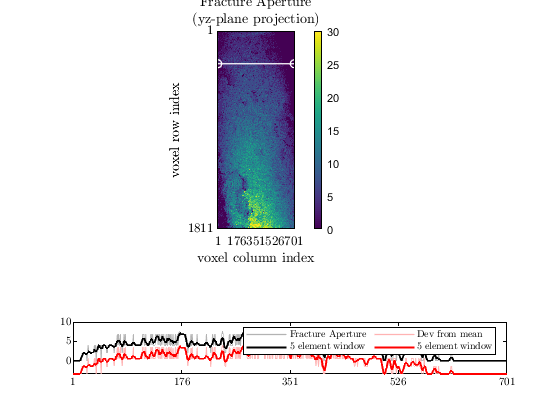

legend('NumColumns',2);


aProfilefft = myfft(aProfile, 1/dX);
aProfiledevfft = myfft(aProfile-mean(aProfile),1/dX);

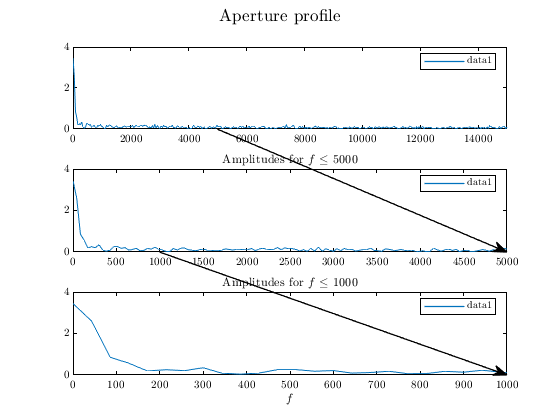

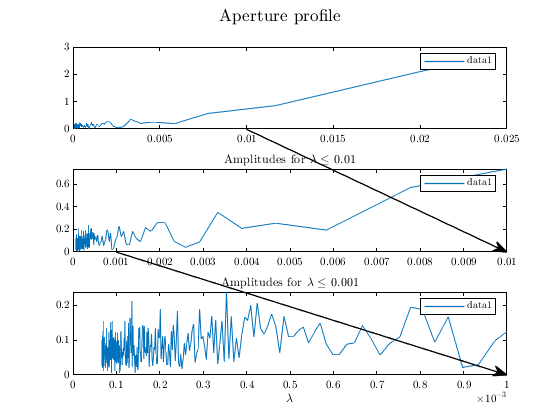

plotfft(aProfilefft,[5000 1000], [1e-2 1e-3], 'Aperture profile');

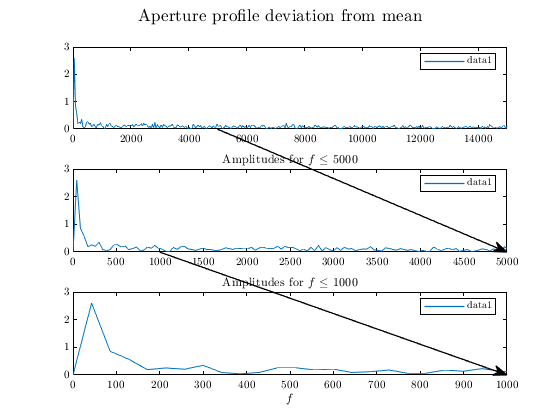

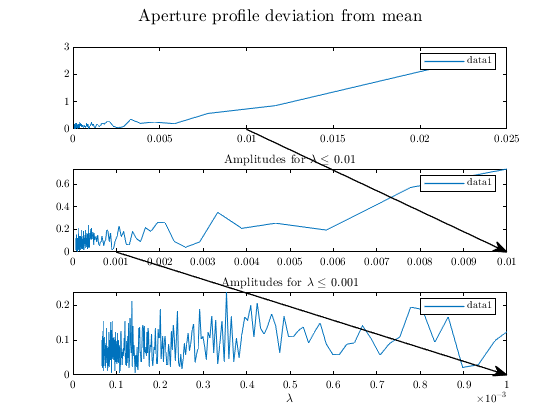

plotfft(aProfiledevfft,[5000 1000], [1e-2 1e-3], 'Aperture profile deviation from mean');

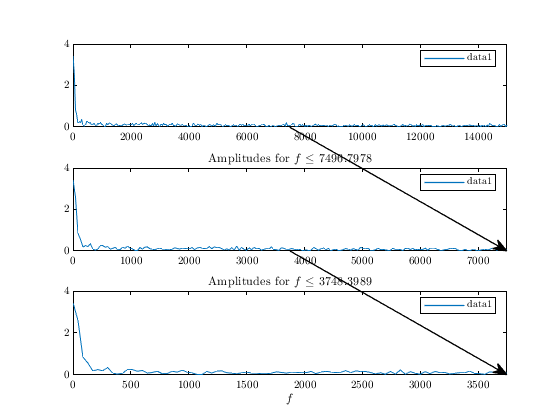

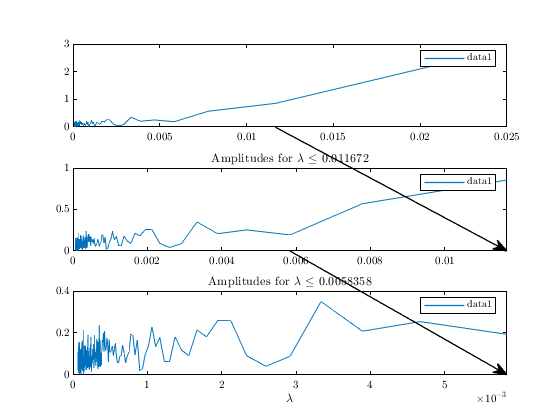

plotfft(aProfilefft);

#### Loading an actual image to determine the proper values of the fracture and the matrix binary image

% navigate to the correct directory 
if exist('goto','file')
    goto(3); % this is my way of going to the project file
end

sevenAFracturedImageFileName = 'sevenA_fractured_image.mat';
sevenAFracturedImageFilePath = fullfile('prototyping','7A_fractured',sevenAFracturedImageFileName);

% loading the data
dataWasNotSaved = false; % this assumes data was already saved previously
if dataWasNotSaved
    data = loadImageSeq(fullfile('..','..','data','Bland','7A_fractured','8bitJPG'),'jpg'); %#ok<UNRCH> 
    save(sevenAFracturedImageFilePath,'data','-v7.3','-mat');
else
    disp('loading from variable directly ...');
    load(sevenAFracturedImageFilePath);
    disp('loading completed');
end 

loading from variable directly ...


loading completed


sevenA.original = data;

#### Displaying a slice of the data

sliceIndex = 800;
image7aSlice = uint8(sevenA.original.image(:,:,sliceIndex));
image7a = imadjust(image7aSlice,[0 .35]);
res = 33.3*1e-3; %[mm]
figure
colormap gray
% setting world reference 
worldRef = imref2d(size(image7a),res,res);
imgout = imshow(image7a,worldRef);

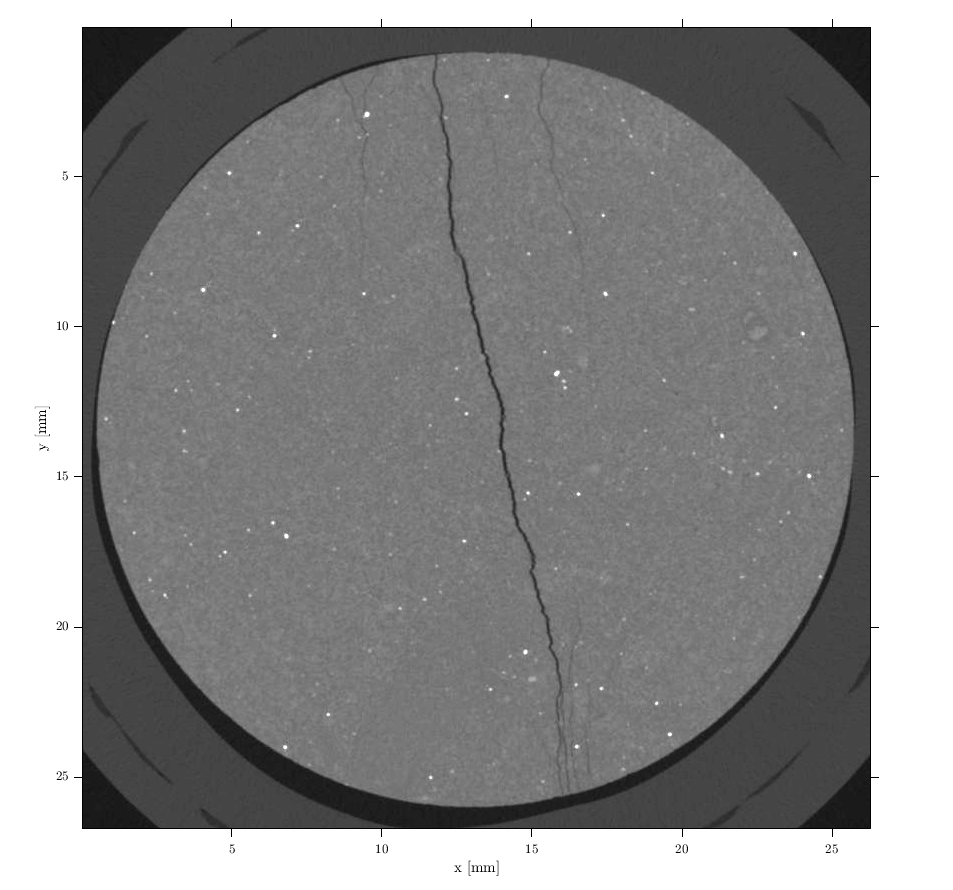

axis image
xlabel('x [mm]');
ylabel('y [mm]');
ax = gca;
% ax.CLim = [0 100];
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;

#### In order to use the synthetic model properly, we need to quantify the noise, and  the mean gray values of the matrix and the fracture in the image. I stopped working on this, will come back to it later.

I started working on this, but encountered some issues regarding fitting a Gaussian through a fracture, and I stopped working on it for now

% Determine the profile along which I will show the gray values
lineXWorldCoord = [13.25 14.25];
lineYWorldCoord = [12 12];
[cx,cy,c0,xl,yl] = improfile(worldRef.XWorldLimits,worldRef.YWorldLimits,image7aSlice,lineXWorldCoord,lineYWorldCoord);
[lineXIndexCoord,lineYIndexCoord] = worldRef.worldToIntrinsic(xl,yl);
aimg = insertMarker(image7a,[lineXIndexCoord lineYIndexCoord],'x','Size',8);
aimg = insertShape(aimg,'Line',[lineXIndexCoord(1), lineYIndexCoord(1), lineXIndexCoord(2), lineYIndexCoord(2)],'Color','r','LineWidth',1);

figure
imshow(aimg, worldRef);

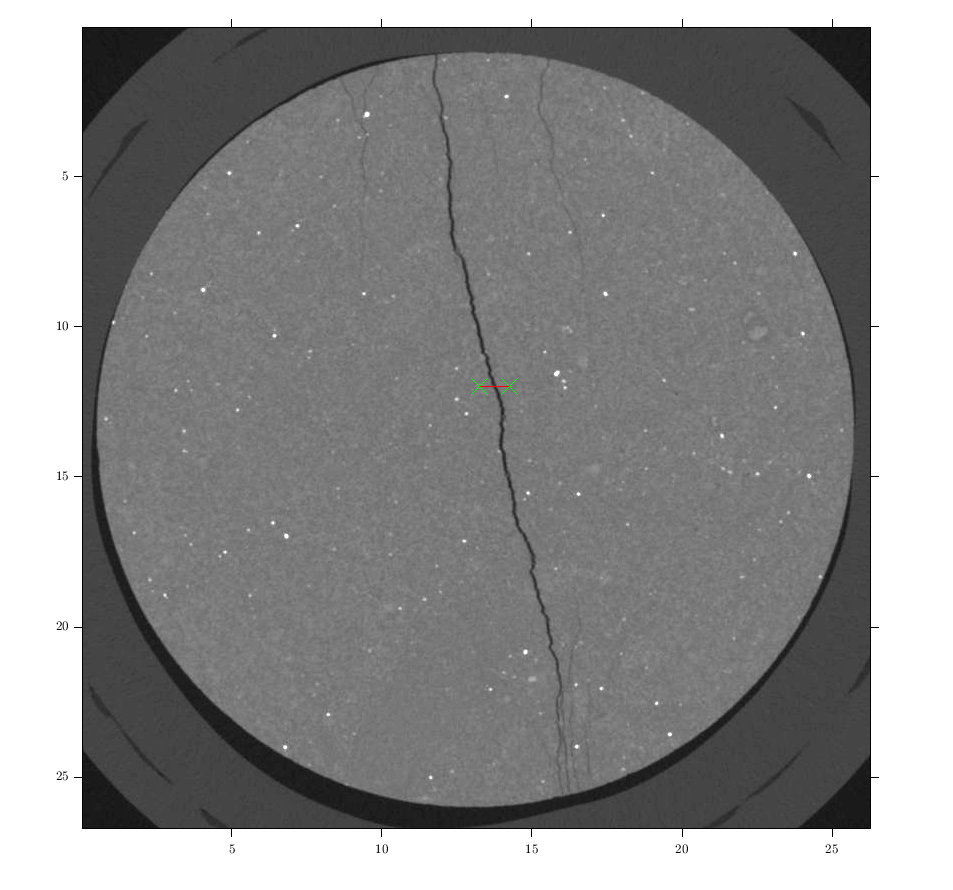

ax = gca;
ax.CLim = [0 100];
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;

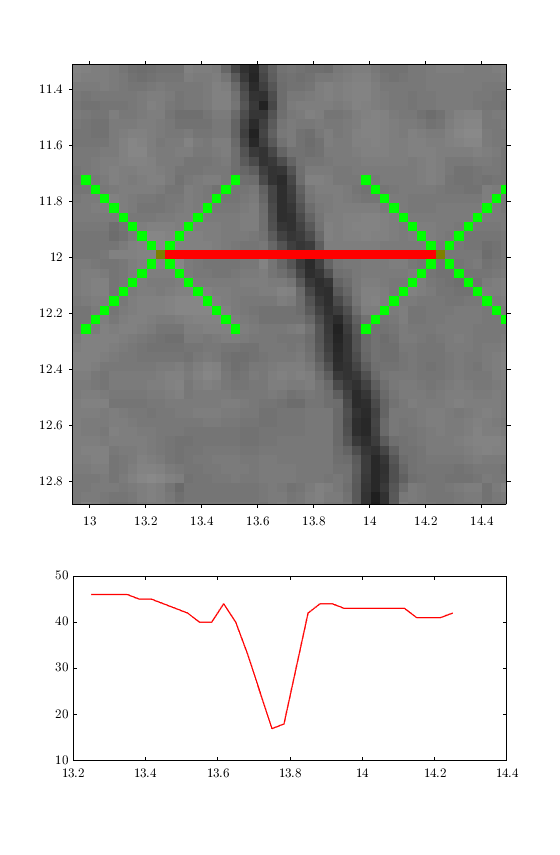

figure('Position',[681 124 560 855]);
subplot(3,2,1:4);
imshow(aimg, worldRef);
ax = gca;
ax.CLim = [0 100];
ax.XAxis.Exponent = 0;
ax.YAxis.Exponent = 0;
xlim([12.94 14.49])
ylim([11.31 12.88])

subplot(3,2,5:6);
newcx = cx-cx(1); newcy = cy-cy(1); 
r = sqrt(newcx.^2 + newcy.^2) + lineXWorldCoord(1);
plot(r,c0,'r')

# Side Notes

## Online University Physics book

In an attempt to understand the difference between amplitude and power, I found the following link that explains power very well: [https://openstax.org/books/university-physics-volume-1/pages/16-4-energy-and-power-of-a-wave#:~:text=The%20time%2Daveraged%20power%20of,by%20a%20factor%20of%20four.](https://openstax.org/books/university-physics-volume-1/pages/16-4-energy-and-power-of-a-wave#:~:text=The%20time%2Daveraged%20power%20of,by%20a%20factor%20of%20four.)

The link is part of an online text book on university physics.

# References

Cerna, M., and A. F. Harvey, 2000, The Fundamentals of FFT-Based Signal Analysis and Measurement: Application Note 041, National Instruments.  

Chuan-Zheng Lee (2017). *Signals and the frequency domain*. (pdf). Available from: <https://web.stanford.edu/class/archive/engr/engr40m.1178/slides/signals.pdf>. [Accessed 02/28/2022 ].

Hopkins, D. L., N. G. W. Cook, and L. R. Myer, 1987, Fracture Stiffness And Aperture As A Function Of Applied Stress And Contact Geometry: , ARMA-87-0673.

Mavko, G. M., and A. Nur, 1978, The effect of nonelliptical cracks on the compressibility of rocks: Journal of Geophysical Research, **83**, 4459.

# Helper functions

function result = myfft(input, samplingFrequency)
result.fft = fft(input);
nSamples = length(input);

% nSamples = 2^nextpow2(length(input)); result.fft = fft(input,nSamples);

% in the following, normalizing by the number of samples is simply part of
% the algorith. I did not look much further into it, and I don't think it
% matters too much
result.p2 = abs(result.fft/length(input));

% computing the signle side band, or singles-sided spectrum, we take the
% first half of P2. Note that P2(1) is the DC or zero-frequencye componenet
result.p1 = result.p2(1:floor(nSamples/2)+1);

% since the first element of the P1 is the DC element, we multiple the rest
% by 2 which is equivalent to applying the Hilbert transform (based on the
% link above!)
result.p1(2:end) = 2*result.p1(2:end);

% to find the x-axis, we need to do the following. I need to study this
% further to better understand it.
result.f1 = (0:(nSamples/2))*(samplingFrequency/nSamples);
result.f2 = f2fromf1(result.f1, nSamples);
result.lambda   = fliplr(1./result.f1);
result.lambdaP1 = fliplr(result.p1);
result.phi2 = angle(result.fft);
result.phi1 = result.phi2(1:floor(nSamples/2)+1);
end

function [x, y] = getRotated2DCoordinates(x,y,deg)
theta = 2*pi/180 * deg; 

B = [cos(theta)  -sin(theta);
     sin(theta) cos(theta)];

tmp = B*[x(:)';y(:)'];
originalSize = size(x);
x = reshape(tmp(1,:),originalSize);
y = reshape(tmp(2,:),originalSize);
end

function output = c(c0,nu,mu,b,P)
% the crack as a function of pressure P and the material properties
output = c0*sqrt(1 - ((2*(1-nu)/(3*mu*(b/c0)))*P));
end

function output = U(c0,c,b,x,x0)
% one sided (y-axis) shape
output = 2*b* (c./c0).^3 * (1 - ((x-x0)./c).^2).^(3/2);
end

function crack = getCrack(material, original, dx, rotation_deg, P)
crack.c0 = original.c;
crack.b0 = original.b;
crack.x0 = original.x0;
crack.dx = dx;
% determine the deformed c
crack.c = real(c(original.c,material.nu,material.mu,original.b,P));
% crack.alpha = crack.b
crack.P = P;
if rotation_deg == 0
    % define the coordinates that include the closed portion of the crack
    crack.x = -original.c+original.x0:dx:original.c+original.x0;
    crack.yplus =  U(crack.c0, crack.c, crack.b0, crack.x, crack.x0);
    crack.yminus= -U(crack.c0, crack.c, crack.b0, crack.x, crack.x0);
    crack.aperture = real(crack.yplus) - real(crack.yminus);
    
    % I want to add mean displacement
    
    crack.b     = max(crack.aperture)/4;
    crack.alpha = (2*crack.b)/(crack.c);
    
    % define the coordinates that do NOT include the close portoin of the crack
    % this will be different only inf P ~= 
    crack.x2 = -crack.c+original.x0:dx:crack.c+original.x0;
    crack.yplus2 =  U(crack.c0, crack.c, crack.b0, crack.x2, crack.x0);
    crack.yminus2= -U(crack.c0, crack.c, crack.b0, crack.x2, crack.x0);
    crack.aperture2 = real(crack.yplus2) - real(crack.yminus2);
    
    % there are multiple different types of means
    crack.apertureMean(1) = mean(crack.aperture);
    crack.apertureMean(2) = sum(crack.aperture)*crack.dx./(2*crack.c);
    crack.apertureMean(3) = trapz(crack.x,crack.aperture)./(2*crack.c);
    aperture = @(x) 2*(2*crack.b* (crack.c./crack.c0).^3 * (1 - ((x-crack.x0)./crack.c).^2).^(3/2));
    crack.apertureMean(4) = integral(aperture,crack.x0-crack.c,crack.x0+crack.c)./(2*crack.c);
    for k = 1:4
        crack.apertureDeviationFromMean(k,:) = crack.aperture - crack.apertureMean(k);
        crack.apertureDeviationFromMean2(k,:) = crack.aperture2 - crack.apertureMean(k);
    end
else
    error('Rotation not implemeted yet');
%     [crack.xplus, crack.yplus]   = getRotated2DCoordinates(crack.x, crack.yplus, rotation_deg);
%     [crack.xminus, crack.yminus] = getRotated2DCoordinates(crack.x, crack.yminus, rotation_deg);
end
end

function crackBinary = getCrackBinary(crack)
crackBinary.x = crack.x(1):crack.dx:crack.x(end);
tmp = abs([min(real(crack.yminus)), max(real(crack.yplus))]);
crackBinary.y = -max(tmp):crack.dx:max(tmp); 
[x, y] = meshgrid(crackBinary.x,crackBinary.y);

% the following commented lines are for the rotation implementation
% originalSize = size(xx);
% [xx, yy] = getRotated2DCoordinates(xx,yy,deg);

crackBinary.image = ~and((y - real(U(crack.c0, crack.c, crack.b0, x, crack.x0))) < 0, ...
                         (y + real(U(crack.c0, crack.c, crack.b0, x, crack.x0))) > 0);
end

function [repx, repy] = getReplicatesAlongX(x,y,n)
repx = zeros(1,numel(x)*n);
for i = 1:n
    repx(((i-1)*length(x)+1):i*length(x)) = x + x(end)*(i-1);
end
repy = repmat(y,1,n);
end

function figs = plotfft(fftresult, freqLims, lambdaLims, mytitle)
if nargin < 4
    mytitle = '';
end
if nargin < 3
    mytitle = '';
    lambdaLims = fftresult.lambda(end-1) * [1/2 1/4];
end
if nargin < 2
    mytitle = '';
    lambdaLims = fftresult.lambda(end-1) * [1/2 1/4];
    freqLims = max(fftresult.f1) * [1/2 1/4];
end
%result = myfft(input, samplingFrequency);
figs(1).fig = figure;
subplot(3,1,1);
plot(fftresult.f1, fftresult.p1); hold on;
figs(1).axs(1) = gca;
figs(1).axs(1).XLim = [min(fftresult.f1), max(fftresult.f1)];
freqAxisLim= figs(1).axs(1).XLim(end);
legend('Location','northeast');

subplot(3,1,2);
plot(fftresult.f1, fftresult.p1); hold on;
title(['Amplitudes for $f \le$ ',num2str(freqLims(1))])
figs(1).axs(2) = gca;
figs(1).axs(2).XLim = [0 freqLims(1)];
legend('Location','northeast');


subplot(3,1,3);
plot(fftresult.f1, fftresult.p1); hold on;
title(['Amplitudes for $f \le$ ',num2str(freqLims(2))])
figs(1).axs(3) = gca;
figs(1).axs(3).XLim = [0 freqLims(2)];
legend('Location','northeast');
xlabel('$f$');

% plot a line between the subplots to relate them to one another
sgtitle(mytitle); pause(.02); % the pause is to help the super title to render correctly (shrug)
annotation(figs(1).fig,'arrow',[figs(1).axs(1).Position(1)+figs(1).axs(1).Position(3)*(freqLims(1)/freqAxisLim)  (figs(1).axs(2).Position(1)+figs(1).axs(2).Position(3))],[figs(1).axs(1).Position(2) figs(1).axs(2).Position(2)]);
annotation(figs(1).fig,'arrow',[figs(1).axs(2).Position(1)+figs(1).axs(2).Position(3)*(freqLims(2)/freqLims(1)) (figs(1).axs(3).Position(1)+figs(1).axs(3).Position(3))],[figs(1).axs(2).Position(2) figs(1).axs(3).Position(2)]);

%%% 
figs(2).fig = figure;
subplot(3,1,1);
plot(fftresult.lambda, fftresult.lambdaP1); hold on;
figs(2).axs(1) = gca;
lambdaAxisLim= figs(2).axs(1).XLim(end);
legend('Location','northeast');

subplot(3,1,2);
plot(fftresult.lambda, fftresult.lambdaP1); hold on;
title(['Amplitudes for $\lambda \le$ ',num2str(lambdaLims(1))])
figs(2).axs(2) = gca;
figs(2).axs(2).XLim = [0 lambdaLims(1)];
legend('Location','northeast');


subplot(3,1,3);
plot(fftresult.lambda, fftresult.lambdaP1); hold on;
title(['Amplitudes for $\lambda \le$ ',num2str(lambdaLims(2))])
figs(2).axs(3) = gca;
figs(2).axs(3).XLim = [0 lambdaLims(2)];
legend('Location','northeast');
xlabel('$\lambda$');

% plot a line between the subplots to relate them to one another
sgtitle(mytitle); pause(.02); % the pause is to help the super title to render correctly (shrug)
annotation(figs(2).fig,'arrow',[figs(2).axs(1).Position(1)+figs(2).axs(1).Position(3)*(lambdaLims(1)/lambdaAxisLim)  (figs(2).axs(2).Position(1)+figs(2).axs(2).Position(3))],[figs(2).axs(1).Position(2) figs(2).axs(2).Position(2)]);
annotation(figs(2).fig,'arrow',[figs(2).axs(2).Position(1)+figs(2).axs(2).Position(3)*(lambdaLims(2)/lambdaLims(1)) (figs(2).axs(3).Position(1)+figs(2).axs(3).Position(3))],[figs(2).axs(2).Position(2) figs(2).axs(3).Position(2)]);
end

function result = fftroundtrip(input,P)
% fftroundtrip
% in order to reconstruct the ifft given the amplitude
result.ref.fft  = myfft(input);
%result.def.
result.ifft = myifft(result.fft);
end


function p2 = p2fromp1(p1,n)
% I want to use this when reconstructing the aperture from its fft
% n = number of samples of the fft output.
if mod(n,2) == 0
    p2shifted = [fliplr(p1), p1(2:end-1)];
else
    p2shifted = [fliplr(p1), p1(2:end)];
end
p2 = ifftshift(p2shifted);
end

function y = yfromp1(p1,phi,n)
% reconstructing y = fft(x) from p1
% n = number of samples of the fft output.
p2 = p2fromp1(p1,n);
p2(2:end) = p2(2:end)./2;
y = p2 * n;
y = y .* (cos(phi) + 1i.*sin(phi));
end

function f2 = f2fromf1(f1,n)
% I want to use this when reconstructing the aperture from its fft
% n: is the number of samples of the fft output.
if mod(n,2) == 0
    f2shifted = [-fliplr(f1), f1(2:end-1)];
else
    f2shifted = [-fliplr(f1), f1(2:end)];
end
f2 = ifftshift(f2shifted);
end